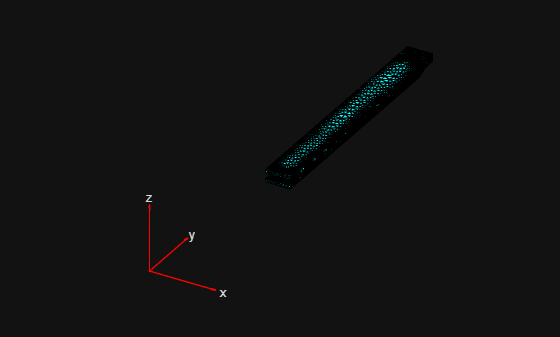

clearvars;
load("droneArmMaterials.mat")

%To get information from file do: materials(i).(TopRowName)
%Ex. materials(1).name will give me Carbon Fiber Composite (CFRP)
Max_mats = length(materials);
MaxThrust = 4; %(kg)
DroneWeightAllowed = MaxThrust/2; %(kg)
MinPayLoad = 0.5; %(kg)
DroneComps = 1; %(kg)
DroneArm1 = zeros(1,6)'; %(kg)
PayloadMax1 = zeros(1,6)'; %(kg)

DroneArm2 = zeros(1,6)'; %(kg)
PayloadMax2 = zeros(1,6)'; %(kg)

gm1 = importGeometry("Nice.STL");
gm2 = importGeometry("TriangleArm.STL");
scale(gm1, 1E-3);
scale(gm2, 1E-3);

md1 = femodel(AnalysisType="structuralStatic", Geometry = gm1); %Model is in mm
md2 = femodel(AnalysisType="structuralStatic", Geometry = gm2);



md1 = generateMesh(md1, Hmin=.0005, Hmax=1);
md2 = generateMesh(md2, Hmin=.0005, Hmax=1);
%Set a H-max

%figure
pdemesh(md1);

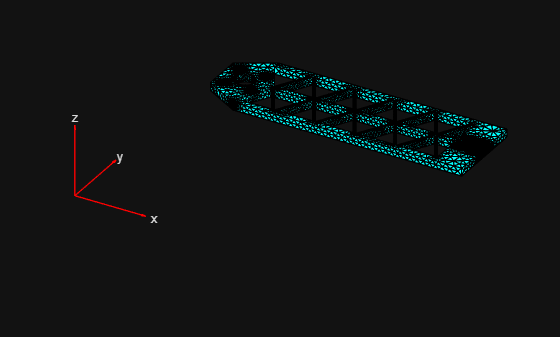

%figure
pdemesh(md2);

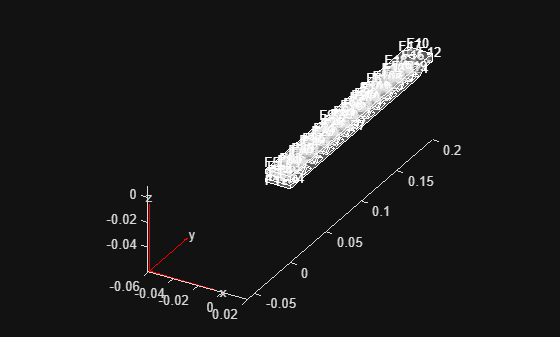



figure
pdegplot(md1,FaceLabels="on", FaceAlpha=.3);

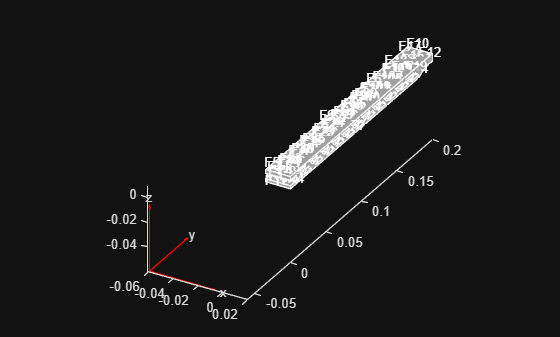

figure
pdegplot(md1,FaceLabels="on", FaceAlpha=1);

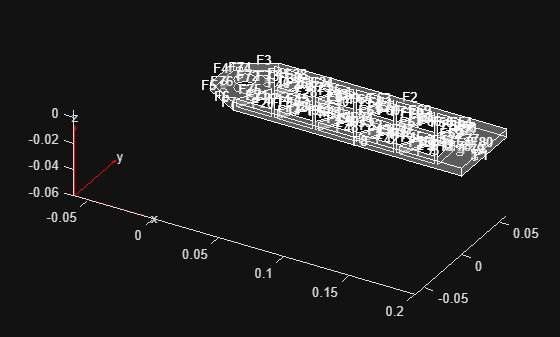


figure
pdegplot(md2,FaceLabels="on", FaceAlpha=0.3);

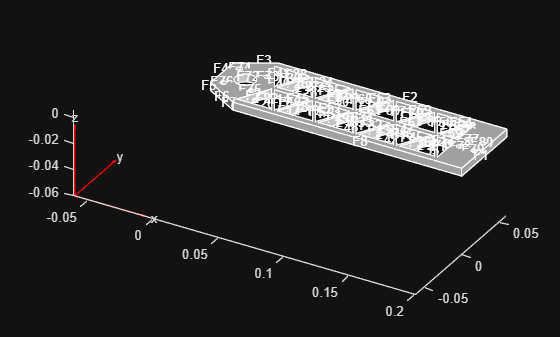

figure
pdegplot(md2,FaceLabels="on", FaceAlpha=1);


mass1 = zeros(1,Max_mats)';
mass2 = zeros(1,Max_mats)';


names = strings(1,Max_mats)'; %Holds names of materials in a vector col

vol1=volume(md1.Geometry.Mesh); %vol1 is m^3
vol1c = max(md1.Geometry.Vertices(:,1))*max(md1.Geometry.Vertices(:,2))*max(md1.Geometry.Vertices(:,3));
Useable1 = strings(1,Max_mats)'; %Vector col to display usability on table
cost1 = zeros(1,Max_mats)';

vol2=volume(md2.Geometry.Mesh); %vol1 is m^3
vol2c = max(md2.Geometry.Vertices(:,1))*max(md2.Geometry.Vertices(:,2))*max(md2.Geometry.Vertices(:,3));
Useable2 = strings(1,Max_mats)'; %Vector col to display usability on table
cost2 = zeros(1,Max_mats)';

%Calc for arm weights
%Test for the model 1's weight
for i = 1:Max_mats
    names(i) = materials(i).name;
    DroneArm1(i) = vol1 * materials(i).rho_kg_m3;
    PayloadMax1(i) = DroneWeightAllowed - DroneArm1(i) - DroneComps;
    cost1(i) = vol1c * (materials(i).cost_USD_per_m^3);
end


for i = 1:Max_mats
    names(i) = materials(i).name;
    DroneArm2(i) = vol2 * materials(i).rho_kg_m3;
    PayloadMax2(i) = DroneWeightAllowed - DroneArm2(i) - DroneComps;
    cost2(i) = vol2c * (materials(i).cost_USD_per_m)^3;

end


%Now add restraints and settings for specific model
%F26 or 25 force hole (Apply force in +y direction)
%12,18,10,16,14 attach points
md1.FaceBC([2,3,4,5,13,14,15,20]) = faceBC(Constraint="fixed");
%md1.FaceLoad(16) = faceLoad(SurfaceTraction= [0;0;(9.8/(pi*0.00287218^2))]);
md1.FaceLoad(16) = faceLoad(SurfaceTraction= [0;0;9.8/(2*pi*0.002*.01)]);
md1.CellLoad = cellLoad(Gravity=[0 0 -9.8]);
%Vector 
md2.FaceBC([77,78,79,80]) = faceBC(Constraint="fixed");
%md2.FaceLoad(11) = faceLoad(SurfaceTraction= [0;0;9.8/(pi*0.002^2)]);
md2.FaceLoad(72) = faceLoad(SurfaceTraction= [0;0;9.8/(pi*0.0075*0.006)]);
md2.CellLoad = cellLoad(Gravity=[0 0 -9.8]);

Max_Stress1 = zeros(1,6)';
Max_Disp1 = zeros(1,6)';
FoS1 = zeros(1,6)';
for i = 1:Max_mats 

    md1.MaterialProperties = ...
        materialProperties(YoungsModulus=materials(i).E_Pa, ...
        PoissonsRatio=materials(i).nu, ...
        MassDensity=materials(i).rho_kg_m3);
    
    switch i
        case 1
            Model_1_result_CFRP = solve(md1);
            Max_Stress1(i) = max(Model_1_result_CFRP.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_CFRP.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 2
            Model_1_result_Al_Alloy = solve(md1);
            Max_Stress1(i) = max(Model_1_result_Al_Alloy.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_Al_Alloy.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 3
            Model_1_result_GFRP = solve(md1);
            Max_Stress1(i) = max( Model_1_result_GFRP.VonMisesStress);
            Max_Disp1(i) = max( Model_1_result_GFRP.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 4
            Model_1_result_PLA = solve(md1);
            Max_Stress1(i) = max(Model_1_result_PLA.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_PLA.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 5
            Model_1_result_ASB = solve(md1);
            Max_Stress1(i) = max(Model_1_result_ASB.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_ASB.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 6
            Model_1_result_Wood = solve(md1);
            Max_Stress1(i) = max(Model_1_result_Wood.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_Wood.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
   
    end


end



%For model 2
Max_Stress2 = zeros(1,6)';
Max_Disp2 = zeros(1,6)';
FoS2 = zeros(1,6)';
for i = 1:Max_mats 

    md2.MaterialProperties = ...
        materialProperties(YoungsModulus=materials(i).E_Pa, ...
        PoissonsRatio=materials(i).nu, ...
        MassDensity=materials(i).rho_kg_m3);

    switch i
        case 1
            Model_2_result_CFRP = solve(md2);
            Max_Stress2(i) = max(Model_2_result_CFRP.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_CFRP.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 2
            Model_2_result_Al_Alloy = solve(md2);
            Max_Stress2(i) = max(Model_2_result_Al_Alloy.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_Al_Alloy.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 3
            Model_2_result_GFRP = solve(md2);
            Max_Stress2(i) = max( Model_2_result_GFRP.VonMisesStress);
            Max_Disp2(i) = max( Model_2_result_GFRP.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 4
            Model_2_result_PLA = solve(md2);
            Max_Stress2(i) = max(Model_2_result_PLA.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_PLA.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 5
            Model_2_result_ASB = solve(md2);
            Max_Stress2(i) = max(Model_2_result_ASB.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_ASB.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 6
            Model_2_result_Wood = solve(md2);
            Max_Stress2(i) = max(Model_2_result_Wood.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_Wood.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);

    end


end

 for i=1:Max_mats
    %Check to see if Minimum payload weight is hit.
    if PayloadMax1(i) >= MinPayLoad && FoS1(i) >= 2 && Max_Disp1(i) <= 0.001  
        Useable1(i) = 'Yes';
    else
        Useable1(i) = 'No';
    end

    %Check to see if Minimum payload weight is hit.
    if PayloadMax2(i) >= MinPayLoad && FoS2(i) >= 2 && Max_Disp2(i) <= 0.001  
        Useable2(i) = 'Yes';
    else
        Useable2(i) = 'No';
    end
 end

disp('|');disp('|');disp('|');

|
|
|


disp('Table For Arm 1')

Table For Arm 1


Show1 = table();
Show1.Material = names;
Show1.Mass_of_Arm_kg=DroneArm1;
Show1.Max_Payload_kg = PayloadMax1;
Show1.Acceptable = Useable1;
Show1.Max_Disp = Max_Disp1;
Show1.Max_Stress = Max_Stress1;
Show1.Factor_of_Safety = FoS1;
Show1.Cost = cost1;
Show1.Total_Cost = cost1*4;
disp(Show1)

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable     Max_Disp     Max_Stress    Factor_of_Safety       Cost       Total_Cost
    _______________________________    ______________    ______________    __________    __________    __________    ________________    __________    __________

    "Carbon Fiber Composite (CFRP)"       0.043951          0.95605          "Yes"       0.00022349    1.3335e+07         44.994             1.0886       4.3545 
    "Aluminum Alloy"                      0.074167          0.92583          "Yes"       0.00022346    1.3078e+07         21.027            0.01701     0.068039 
    "Fiberglass Composite (GFRP)"         0.0


disp('|');disp('|');disp('|');

|
|
|


disp('Table For Arm 2')

Table For Arm 2


Show2 = table();
Show2.Material = names;
Show2.Mass_of_Arm_kg=DroneArm2;
Show2.Max_Payload_kg = PayloadMax2;
Show2.Acceptable = Useable2;
Show2.Max_Disp = Max_Disp2;
Show2.Max_Stress = Max_Stress2;
Show2.Factor_of_Safety = FoS2;
Show2.Cost = cost2;
Show2.Total_Cost = cost2*4;
disp(Show2)

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp     Max_Stress    Factor_of_Safety       Cost       Total_Cost
    _______________________________    ______________    ______________    __________    _________    __________    ________________    __________    __________

    "Carbon Fiber Composite (CFRP)"        0.05344          0.94656           "No"       0.0018902    5.2536e+07         11.421             1.9535       7.8141 
    "Aluminum Alloy"                      0.090179          0.90982           "No"       0.0019031     5.227e+07         5.2611           0.030524       0.1221 
    "Fiberglass Composite (GFRP)"          0.0634


%Max_Displacement = max(Result.Displacement.Magnitude)
%Max_Stress = max(Result.VonMisesStress)
%FoS = materials(1).yieldStrength_Pa/Max_Stress

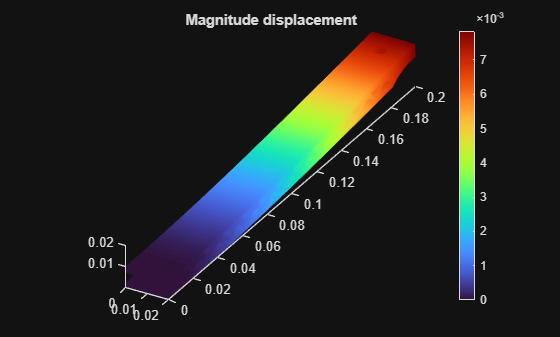

% Data to visualize
meshData = Model_1_result_ASB.Mesh;
nodalData = Model_1_result_ASB.Displacement.Magnitude;
deformationData = Model_1_result_ASB.Displacement;

% Create PDE result visualization
resultViz = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",1.2748, ...
    "Title","Magnitude displacement", ...
    "ColorLimits",[0 0.007844]);


% Clear temporary variables
clearvars meshData nodalData deformationData


% some left over code
%Vtype = ["string", "double", "double", "double", "double", "double", "double"]
%Vname = ["Material", "Max_Z", "Min_Z", "Max_X", "Min_X", "Max_Y", "Min_Y"]
%ResultT = table('Size', [6,7], ...
 %   'VariableTypes',Vtype, ...
 %   'VariableNames',Vname);
%ResultT.Material = names


%subplot(2,3,i)
%pdeplot3D (md.Geometry.Mesh, 'ColorMapData', result.VonMisesStress, 'Deformation', result.Displacement, 'DeformationScaleFactor', 100);
%title(names(i));

